# 通过 PSO 算法进行 PID 参数整定

 
clear;clc

## 1.系统参数设定

 
m = 1;
c = 0;
k = 1;
dt = 0.01;
T = 10;
v0 = 1; % 初速度

% PSO 参数
swarm_size = 32;  % 种群规模
max_iter = 200; % 最大迭代次数
v_mm = [-1 1]; %速度約束
c1 = 1.3; % 局部学习因子
c2 = 1.7; % 全局学习因子
w_mm = [0.1 0.9]; % 时变惯性权重約束
tolerance = 1e-21; % 容许误差

% 定义一个全局变量来存储粒子信息
global K

## 2.基于状态空间搭建系统

 
A = [0 1;
    -k/m -c/m];
B = [0;1/m];
C = [1 0];
D = 0;
sys = ss(A,B,C,D);

R1 = Function_PSO_PID_Rewardfx(8.9797,2.3541,5.3070,sys,dt,T) % 论文的最优奖励

R1 = -57.7006

R2 = Function_PSO_PID_Rewardfx(8.5253,0.0014,5.0831,sys,dt,T) % 论文的最优奖励

R2 = -56.3805

## 3.基于PSO算法对PID进行参数整定

% 创建优化变量
Kp_hat = optimvar("Kp_hat","LowerBound",0,"UpperBound",50);
Ki_hat = optimvar("Ki_hat","LowerBound",0,"UpperBound",50);
Kd_hat = optimvar("Kd_hat","LowerBound",0,"UpperBound",50);

% 设置求解器的初始起点
initialPoint.Kp_hat = repmat(7,size(Kp_hat));
initialPoint.Ki_hat = repmat(7,size(Ki_hat));
initialPoint.Kd_hat = repmat(7,size(Kd_hat));

% 创建问题(最大化奖励函数)
problem = optimproblem("ObjectiveSense","Maximize");

% 定义问题目标
problem.Objective = fcn2optimexpr(@Function_PSO_PID_Rewardfx,Kp_hat,Ki_hat,Kd_hat,sys,...
    dt,T);

% 设置非默认求解器选项
options = optimoptions("particleswarm", ...
    "Display","iter", ...
    "InertiaRange",w_mm, ...
    "MaxIterations",max_iter, ...
    "SelfAdjustmentWeight",c1,...
    "SocialAdjustmentWeight",c2, ...
    "SwarmSize",swarm_size, ...
    "PlotFcn",@pswplotbestf, ...
    'OutputFcn', @myOutputFcn,...
    "FunctionTolerance", tolerance);

% 显示问题信息
show(problem);


  OptimizationProblem : 

	Solve for:
       Kd_hat, Ki_hat, Kp_hat

	maximize :
       Function_PSO_PID_Rewardfx(Kp_hat, Ki_hat, Kd_hat, extraParams{1}, 0.01, 10)

       extraParams


	variable bounds:
       0 <= Kd_hat <= 50

       0 <= Ki_hat <= 50

       0 <= Kp_hat <= 50




% 求解问题
[solution,objectiveValue,reasonSolverStopped] = solve(problem,initialPoint,...
    "Solver","particleswarm","Options",options);

将使用 particleswarm 求解问题。

                                 Best            Mean     Stall
Iteration     f-count            f(x)            f(x)    Iterations
    0              32          -60.64      -1.398e+04        0
    1              64          -60.64       -1.18e+15        0
    2              96          -59.45      -2.408e+08        0
    3             128          -59.45      -2.291e+09        1
    4             160          -59.45      -5.607e+04        2
    5             192          -59.45      -3.757e+08        3
    6             224          -59.45      -3.366e+04        4
    7             256          -58.08           -1151        0
    8             288          -58.08      -5.382e+04        1
    9             320          -58.08      -1.485e+05        2
   10             352          -57.98          -456.6        0
   11             384          -57.31      -4.313e+07        0
   12             416          -56.58      -1.564e+06        0
   13             448   

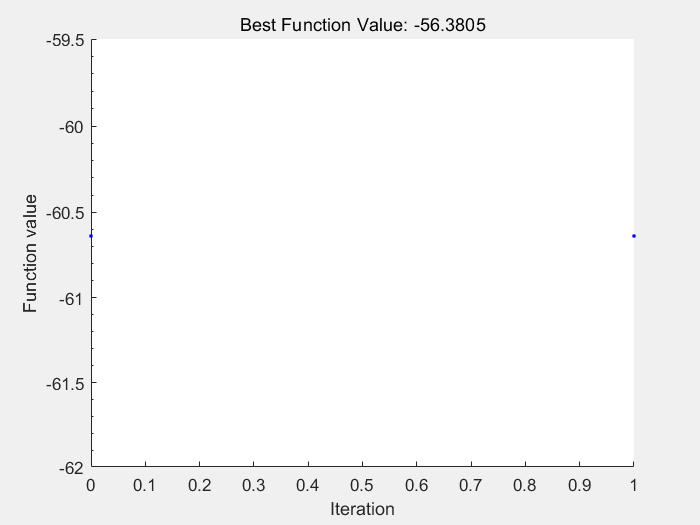

set(gca, 'YScale', 'log'); % 将当前图示的坐标转化为对数坐标

## 为什么优化的结果ki会趋于0


% 显示结果
solution

solution = 包含以下字段的 struct :
    Kd_hat: 5.0830
    Ki_hat: 0
    Kp_hat: 8.5261


reasonSolverStopped

reasonSolverStopped =     SolverConvergedSuccessfully


objectiveValue

objectiveValue = -56.3805

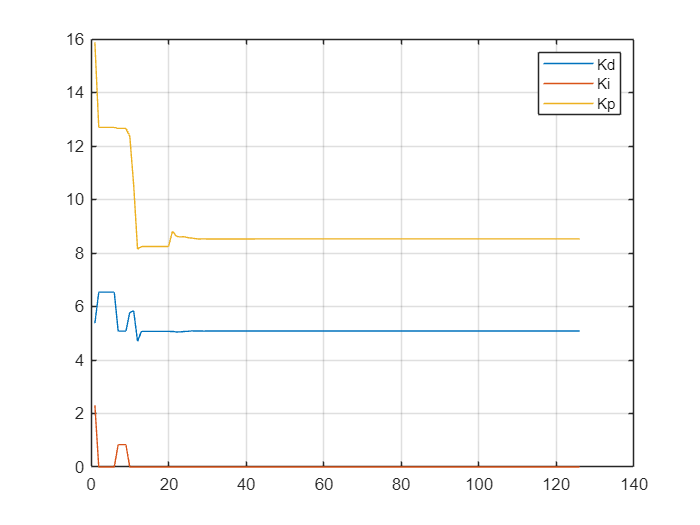

figure
plot(K)
grid on
legend('Kd', 'Ki', 'Kp')


% 清除变量
clearvars Kp_hat Ki_hat Kd_hat initialPoint options reasonSolverStopped objectiveValue

获取每一步的粒子群信息

function stop = myOutputFcn(optimValues, state)
    stop = false;
    global K
    % 优化过程中每一步的信息
    if strcmp(state, 'iter')  % 每一步迭代时
        K(optimValues.iteration,:) = optimValues.bestx;
    end
    if strcmp(state, 'done')
        K = K(1:optimValues.iteration,:);
    end
end